# enae311h hw04

## p02

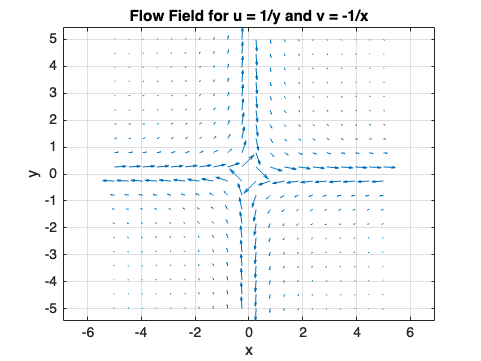

% MATLAB code to plot the flow field for u = 1/y and v = -1/x

% Define the grid range and resolution
x_range = linspace(-5, 5, 20);
y_range = linspace(-5, 5, 20);

% Remove zero to avoid division by zero
x_range(x_range == 0) = [];
y_range(y_range == 0) = [];

% Create a meshgrid for x and y
[X, Y] = meshgrid(x_range, y_range);

% Calculate the velocity components u and v
u = 1 ./ Y;
v = -1 ./ X;

% Handle infinite values resulting from division by zero
u(isinf(u)) = 0;
v(isinf(v)) = 0;

% Limit the maximum magnitude of u and v for better visualization
max_val = 5;
u(u > max_val) = max_val;
u(u < -max_val) = -max_val;
v(v > max_val) = max_val;
v(v < -max_val) = -max_val;

% Plot the flow field using quiver
figure;
quiver(X, Y, u, v, 'AutoScale', 'on');
xlabel('x');
ylabel('y');
title('Flow Field for u = 1/y and v = -1/x');
axis equal;
grid on;

## p03

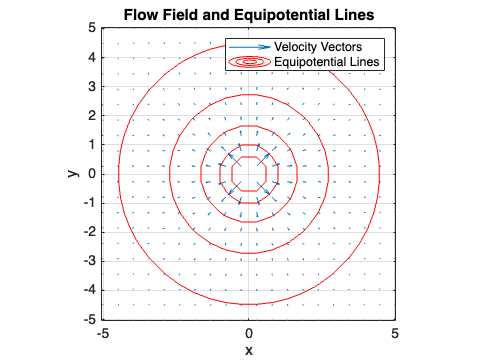

% MATLAB code to plot the flow field for u = x/(x^2 + y^2) and v = y/(x^2 + y^2)
% Also plots the equipotential lines of the velocity potential in cylindrical coordinates

% Define the grid range and resolution
x_range = linspace(-5, 5, 20);
y_range = linspace(-5, 5, 20);

% Create a meshgrid for x and y
[X, Y] = meshgrid(x_range, y_range);

% Calculate the velocity components u and v
denominator = X.^2 + Y.^2;

% Avoid division by zero by setting zero denominators to the smallest
% possible integer MATLAB can handle: 2^(-52)
denominator(denominator == 0) = eps;

u = X ./ denominator;
v = Y ./ denominator;

% Compute the velocity potential phi = ln(r)
R = sqrt(X.^2 + Y.^2);
Phi = log(R);

% Plot the flow field using quiver
figure;
quiver(X, Y, u, v);
xlabel('x');
ylabel('y');
title('Flow Field and Equipotential Lines');
axis equal;
grid on;
hold on;

% Define levels for equipotential lines
phi_levels = -2:0.5:2;

% Plot equipotential lines (lines of constant phi)
contour(X, Y, Phi, phi_levels, 'LineColor', 'r');

legend('Velocity Vectors', 'Equipotential Lines');
hold off;